**Inicio**

clear all
close all
clc

**Generación de imagen con puntos**

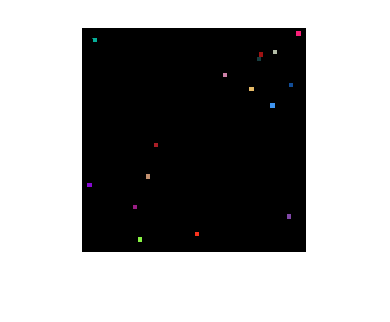

size_i=256;
size_j=256;
photo=zeros(size_i,size_j,3);
points=16;
pos_i= zeros(1,points);
pos_j= zeros(1,points);
color_p= zeros(points,3);
for k =1 : points
    i_1=randi(size_i,1,1);
    j_1=randi(size_j,1,1);
    color=randi(255,1,3);
    for l = 1 : 5
        for n = 1 : 5
            photo(i_1-2+n,j_1-2+l,:)=color;
        end
    end
    pos_i(1,k)=i_1;
    pos_j(1,k)=j_1;
    color_p(k,:)=color;
end
imshow(uint8(photo))

**Generación de mapa de Voronoi**

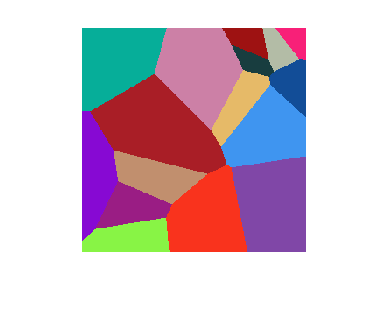

for i=1 : size_i
    for j=1 : size_j
        pashipo=(size_i^2+size_j^2)^(1/2);
        for k=1 : points
            hipo=((abs(pos_i(1,k)-i)^2)+(abs(pos_j(1,k)-j)^2))^(1/2);
            if hipo<pashipo
                pashipo=hipo;
                photo(i,j,:)=color_p(k,:);
            end 
        end 
    end
end
imshow(uint8(photo))

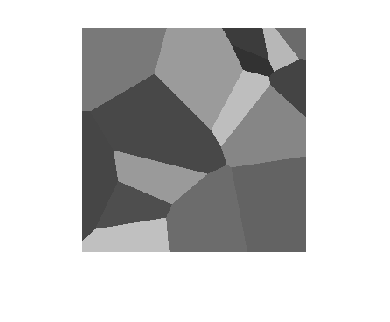

imshow(rgb2gray(uint8(photo)))